
% fit fluorescence intensity distribution to a randomly-labeled hexamer model 
% with known labeling fraction
load('may3data.mat')

nbins=40; % number of bins in histograms
nboot=300; % number of bootstrap samples
global parm_names; % may not be necessary
nmer = 6; % hexamer
f = 0.22; % fraction of labeled monomers
func=@(x, varargin)...
    nmer_gaussian_one_sigma_zeromu_pdf(x, nmer, f, varargin{:});
dataset='F5int';
x=F5int';
size(x)

ans =            1        1489


x = x(x < 8000); % remove outliers
size(x)

ans =            1        1476


% parms -    [xp0 sigma spacing] 
lbounds =    [0, 0, 300]; % constrain lower bounds of parameters
ubounds =    [10, 1000, 2500]; % constrain upper bounds of parameters
init_parm =  [0.29, 600, 1700]; % initial param guesses
fitscript;

fit_parameters = 3×5 table
                Value      Lower_90pct_CI    Upper_90pct_CI    Lower_bound    Upper_bound
               ________    ______________    ______________    ___________    ___________

    xp0        0.047281      0.0094772          0.085805             0             10    
    sigma        515.89         483.83             562.6             0           1000    
    spacing      1050.2         1006.9            1096.3           300           2500    


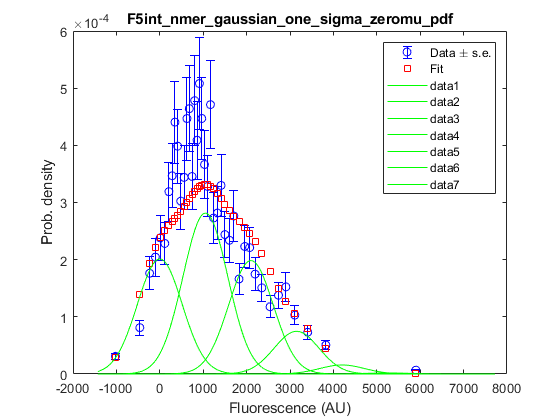

% component plot
xx = min(x):((max(x)-min(x))/1000):max(x); 
parms=phat;
% constrain sum of amplitudes to be < 1:
p0 = parms(1);
ns = 0:nmer;
ps = pdf('Binomial', ns, nmer, f);
ps(1) = ps(1) + p0;
ps = ps ./ sum(ps) ; % normalize amplitudes
mus = ns .* parms(3);
hold on
for i = 1:nmer+1
    distn=makedist('Normal', 'mu', mus(i), 'sigma', parms(2));
    yy = pdf(distn,xx) .* ps(i);
    plot(xx,yy,'-g')
end
hold off

jganalyze_gitinfo()

ans = struct with fields:
    branch: 'master'
      hash: 'e085fcae789768c1de6e795fbd8c480c54f69f79'
    remote: 'origin'
       url: 'https://github.com/gelles-brandeis/jganalyze.git'
